1. Write a program to plot the impulse response coefficients and zero locations for the 4 types of linear phase FIR filters

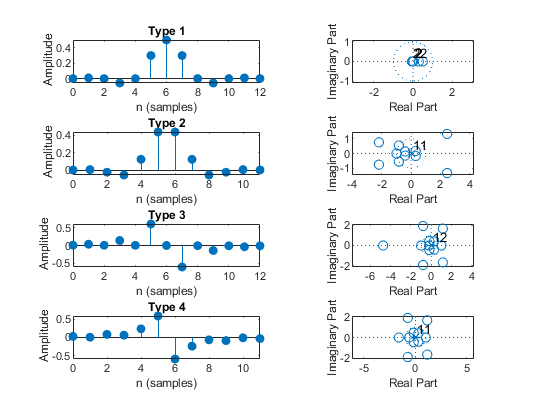

figure();
subplot(421)
b1 = fir1(12,0.5);
impz(b1), title(['Type ' int2str(firtype(b1))])
subplot(422)
zplane(impz(b1))


subplot(423)
b2 = fir1(11,0.5);
impz(b2), title(['Type ' int2str(firtype(b2))])
subplot(424)
zplane(b2)

subplot(425)
b3 = firpm(12,[0.2 0.8],[1 1],'differentiator');
impz(b3), title(['Type ' int2str(firtype(b3))])
subplot(426)
zplane(b3)

subplot(427)
b4 = firpm(11,[0.2 0.8],[1 1],'differentiator');
impz(b4), title(['Type ' int2str(firtype(b4))])
subplot(428)
zplane(b4)

2. (a) Using the function firpmord, estimate the order of a linear-phase low pass FIR filter with the following specifications: passband edge=2kHz, stopband edge=2.5kHz, passband ripple δp = 0.005, stopband ripple δs = 0.005, and sampling rate of 10kHz

rp = 0.005;           % Passband ripple
rs = 0.005;          % Stopband ripple
fs = 10000;        % Sampling frequency
f = [2000 2500];    % Cutoff frequencies
a = [1 0];        % Desired amplitudes
figure();
[n,fo,ao,w] = firpmord(f,a,[rp rs],fs)

n = 47

fo =          0
    0.4000
    0.5000
    1.0000


ao =      1
     1
     0
     0


w =      1
     1


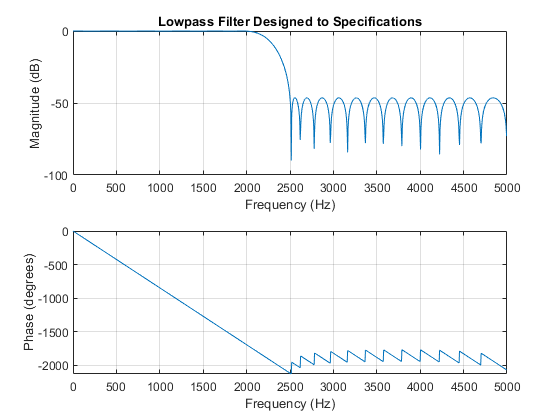

b = firpm(n,fo,ao,w);
freqz(b,1,1024,fs)
title('Lowpass Filter Designed to Specifications')

(b) Repeat Part a. for the following cases: (i)sampling rate of 20kHz,(ii) δp = 0.002 and δs = 0.002, and (iii)stopband edge=2.3kHz. Compare the filter length obtained in each case with that obtained in part a. Comment on the effect of the sampling rate, ripples, and the transition bandwidth on the filter order. 

rp1 = 0.002;           % Passband ripple
rs1 = 0.002;          % Stopband ripple
fs1 = 20000;        % Sampling frequency
f1 = [2000 2300];    % Cutoff frequencies
a1 = [1 0];        % Desired amplitudes
figure();
[n1,fo1,ao1,w1] = firpmord(f1,a1,[rp1 rs],fs1)

n1 = 174

fo1 =          0
    0.2000
    0.2300
    1.0000


ao1 =      1
     1
     0
     0


w1 =     2.5000
    1.0000


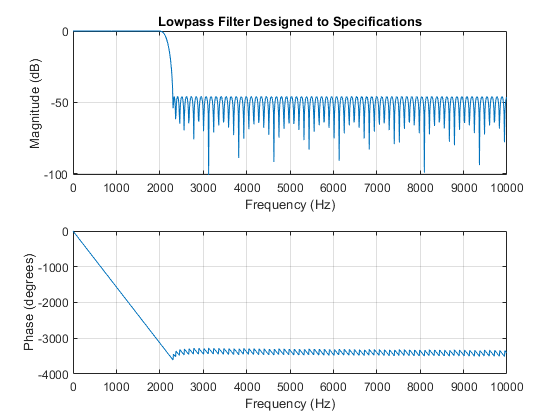

b1 = firpm(n1,fo1,ao1,w1);
freqz(b1,1,1024,fs1)
title('Lowpass Filter Designed to Specifications')

(c) Repeat Part a. using the function kaiserord. Compare the value of the filter order obtained with that obtained in Part a. 

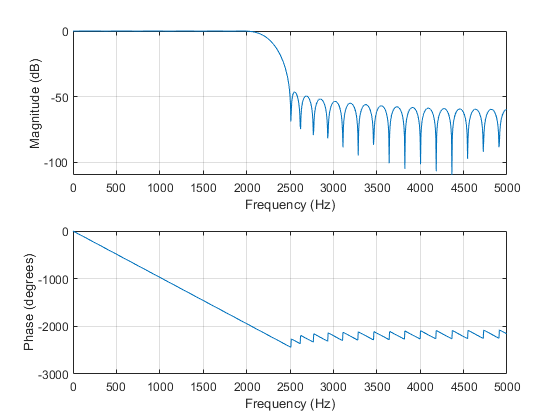

fsamp = 10000;
fcuts = [2000 2500];
a2 = [1 0];
devs = [0.005 0.005];

[n,Wn,beta,ftype] = kaiserord(fcuts,a2,devs,fsamp);
hh = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');

freqz(hh,1,1024,fsamp)

d)Using the function firpmord, estimate the order of a linear-phase bandpass FIR filter with the following specifications: passband edges = 1.8 and 3.6 KHz, stopband edges 1.2 and 4.2 kHz, passband ripple δp = 0.1, stopband ripple δs = 0.02, and sampling rate of 12kHz.

rp = 0.1;           % Passband ripple
rs = 0.02;          % Stopband ripple
fs = 12000;        % Sampling frequency
f = [1200 1800 3600 4200];    % Cutoff frequencies
a = [0 1 0];        % Desired amplitudes
figure();
[n,fo,ao,w] = firpmord(f,a,[rs rp rs],fs)

n = 22

fo =          0
    0.2000
    0.3000
    0.6000
    0.7000
    1.0000


ao =      0
     0
     1
     1
     0
     0


w =      5
     1
     5


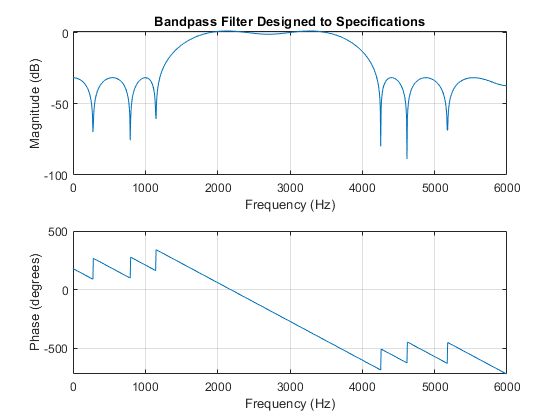

b = firpm(n,fo,ao,w);
freqz(b,1,1024,fs)
title('Bandpass Filter Designed to Specifications')

e)Repeat Part d. using the function kaiserord. Compare the value of the filter order obtained with that obtained in Part d.

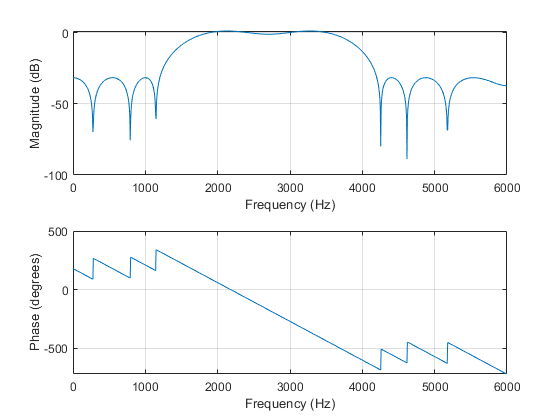


fsamp = 12000;
fcuts = [1200 1800 3600 4200];
a2 = [0 1 0];
devs = [0.02 0.1 0.02];
[n,Wn,beta,ftype] = kaiserord(fcuts,a2,devs,fsamp);
hh = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');

freqz(b,1,1024,fs)

f)Using the function fir1, design a linear-phase FIR lowpass filter meeting the specifications given in Part a. and plot its gain and phase responses. Use the order estimated using firpmord in Part a.

rp = 0.005;           % Passband ripple
rs = 0.005;          % Stopband ripple
fs = 10000;        % Sampling frequency
f = [2000 2500];    % Cutoff frequencies
a = [1 0];        % Desired amplitudes
figure();
[n,fo,ao,w] = firpmord(f,a,[rp rs],fs)

n = 47

fo =          0
    0.4000
    0.5000
    1.0000


ao =      1
     1
     0
     0


w =      1
     1


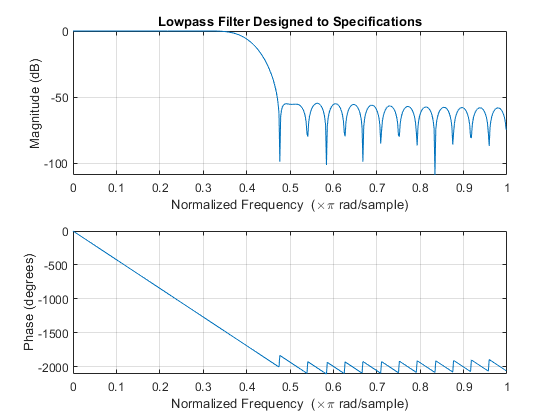

b = fir1(n,(f(1)/fs)*2);
freqz(b,1,512)
title('Lowpass Filter Designed to Specifications')

g)Repeat Part f. using Hanning and Blackman windows

rp = 0.005;           % Passband ripple
rs = 0.005;          % Stopband ripple
fs = 10000;        % Sampling frequency
f = [2000 2500];    % Cutoff frequencies
a = [1 0];        % Desired amplitudes
figure();
[n,fo,ao,w] = firpmord(f,a,[rp rs],fs)

n = 47

fo =          0
    0.4000
    0.5000
    1.0000


ao =      1
     1
     0
     0


w =      1
     1


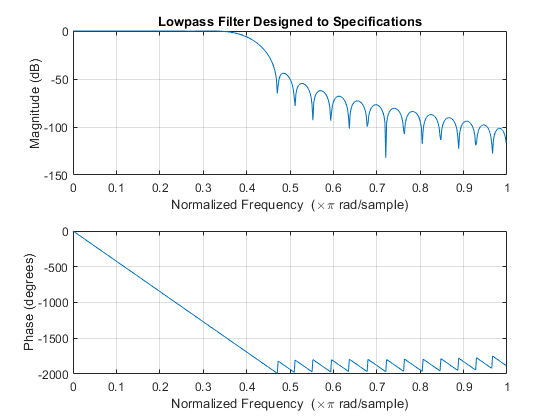

b = fir1(n,(f(1)/fs)*2,"low",hann(n+1));
freqz(b,1,512)
title('Lowpass Filter Designed to Specifications')

rp = 0.005;           % Passband ripple
rs = 0.005;          % Stopband ripple
fs = 10000;        % Sampling frequency
f = [2000 2500];    % Cutoff frequencies
a = [1 0];        % Desired amplitudes
figure();
[n,fo,ao,w] = firpmord(f,a,[rp rs],fs)

n = 47

fo =          0
    0.4000
    0.5000
    1.0000


ao =      1
     1
     0
     0


w =      1
     1


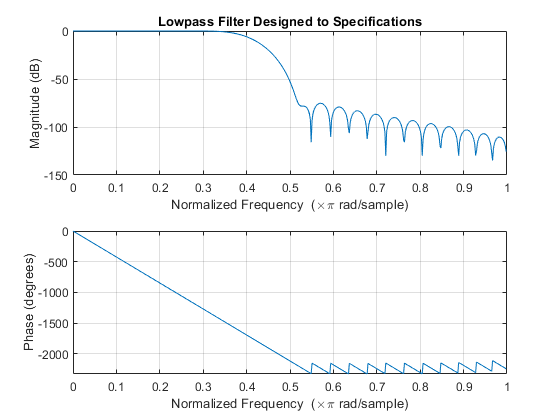

b = fir1(n,(f(1)/fs)*2,"low",blackman(n+1));
freqz(b,1,512)
title('Lowpass Filter Designed to Specifications')

h)Using the function firpm, design a linear-phase FIR lowpass filter meeting the specifications given in Part a. and plot its gain and phase responses.

rp = 0.005;           % Passband ripple
rs = 0.005;          % Stopband ripple
fs = 10000;        % Sampling frequency
f = [2000 2500];    % Cutoff frequencies
a = [1 0];        % Desired amplitudes
figure();
[n,fo,ao,w] = firpmord(f,a,[rp rs],fs)

n = 47

fo =          0
    0.4000
    0.5000
    1.0000


ao =      1
     1
     0
     0


w =      1
     1


b = firpm(n,fo,ao,w);
freqz(b,1,1024,fs)
title('Lowpass Filter Designed to Specifications')

i)Design an FIR lowpass filter using a Kaiser window. The filter specificatoins are: ωp = 0.3π, ωs = 0.4π, and As = 50dB.

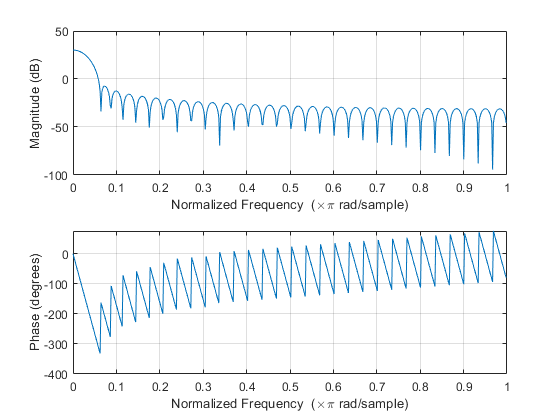

wp = 0.3*pi;
ws = 0.4*pi;
As = 50;

wt = ws - wp;
wc = (wp + ws) / 2;

N = ceil((As - 8) / (2.285 * wt));

% Determine the beta value based on the desired stop-band attenuation
%beta=0.5842(a-2.1)^0.4 +0.07886(A-21) for A=[21 50]
beta = 5.03;

% Compute the Kaiser window
w = kaiser(N + 1, beta);

figure;
freqz(w);

j)Using firpm, design the bandpass filter with specifications in Part d.and order estimated using firpmord.

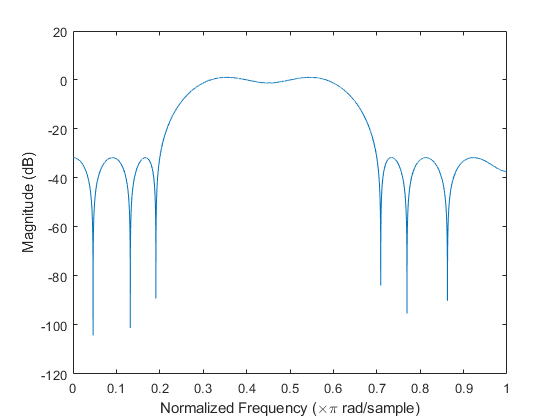

[N, Fo, Ao, W] = firpmord([1.2 1.8 3.6 4.2]*1000, [0 1 0], [0.02 0.1 0.02], 12000);
b = firpm(N, Fo, Ao, W);
[H, w] = freqz(b, 1, 12000);
subplot(111);
plot(w/pi, 20*log10(abs(H)));
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');